# **DSP HW4**

**By: 106061151 劉安得**

## **1. (a)**


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =n{0\ldotp 9}^n u\left\lbrack n\right\rbrack =\left(n+1\right){0\ldotp 9}^n u\left\lbrack n\right\rbrack -{0\ldotp 9}^n u\left\lbrack n\right\rbrack \\
X\left(z\right)=\frac{1}{{\left(1-0\ldotp 9z^{-1} \right)}^2 }-\frac{1}{1-0\ldotp 9z^{-1} }=\frac{0\ldotp 9z^{-1} }{{\left(1-0\ldotp 9z^{-1} \right)}^2 }\\
\tilde{X} \left(e^{i\omega } \right)=\frac{0\ldotp 9e^{-i\omega } }{{\left(1-0\ldotp 9e^{-i\omega } \right)}^2 }
\end{array}$$


## 1. (b)

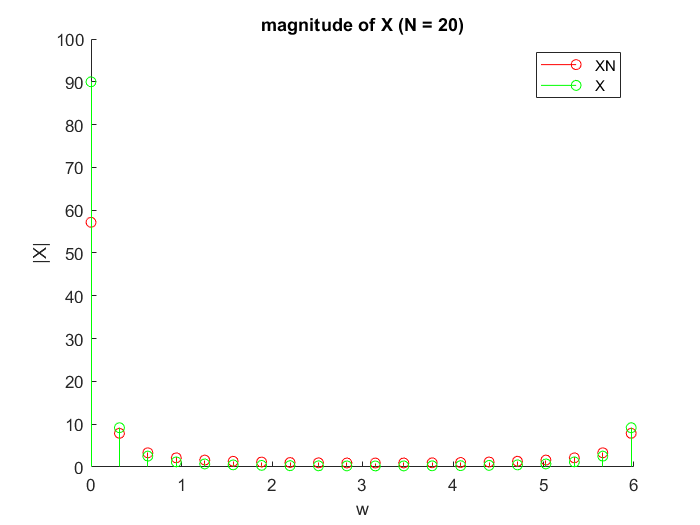

%Prob. 1(b)
N1 = 20;
w1 = linspace(0, 2*pi, N1+1);
n1 = 1:N1;
xn1 = n1.*(0.9.^n1).*heaviside(n1);
XN1 = fft(xn1);
X1 = 0.9*exp(-i*w1)./(1-0.9*exp(-i*w1)).^2;

figure
hold on
stem(w1(1:20), abs(XN1), 'r')
stem(w1(1:20), abs(X1(1:20)), 'g')
title('magnitude of X (N = 20)')
xlabel('w')
ylabel('|X|')
legend('XN','X')
hold off

大部分頻率接近 DTFT，除了在 w = 0 差比較多之外

## 1. (c)

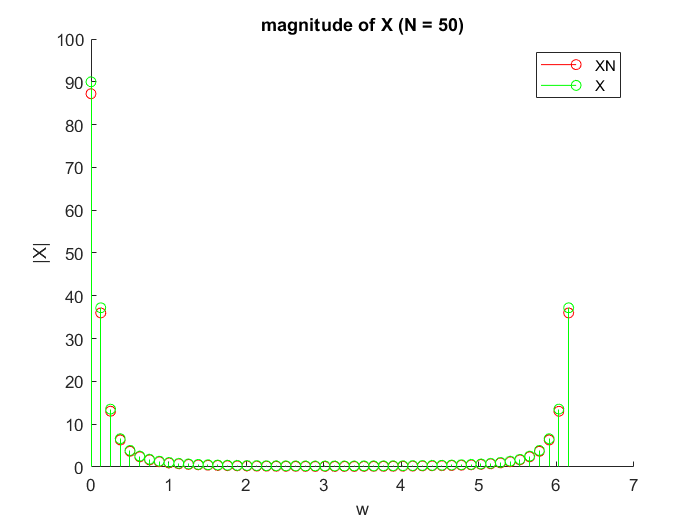

%Prob. 1(c)
N2 = 50;
w2 = linspace(0, 2*pi, N2+1);
n2 = 1:N2;
xn2 = n2.*(0.9.^n2).*heaviside(n2);
XN2 = fft(xn2);
X2 = 0.9*exp(-i*w2)./(1-0.9*exp(-i*w2)).^2;

figure
hold on
stem(w2(1:N2), abs(XN2), 'r')
stem(w2(1:N2), abs(X2(1:N2)), 'g')
title('magnitude of X (N = 50)')
xlabel('w')
ylabel('|X|')
legend('XN','X')
hold off

相較 N = 20, 更接近 DTFT，誤差不大

## 1. (d)

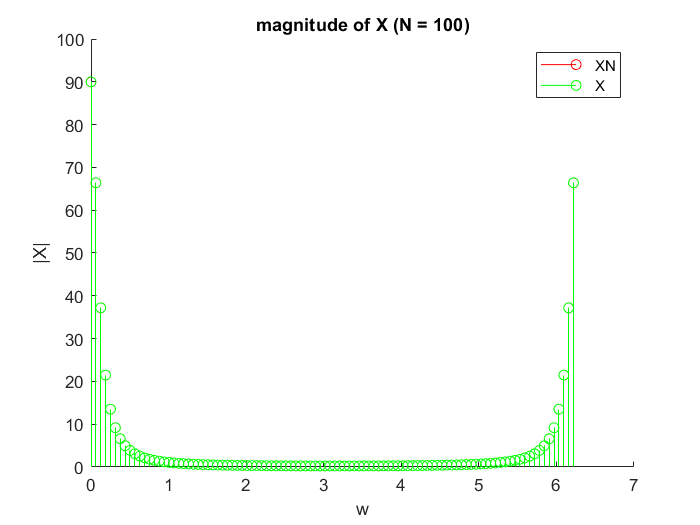

%Prob. 1(d)
N3 = 100;
w3 = linspace(0, 2*pi, N3+1);
n3 = 1:N3;
xn3 = n3.*(0.9.^n3).*heaviside(n3);
XN3 = fft(xn3);
X3 = 0.9*exp(-i*w3)./(1-0.9*exp(-i*w3)).^2;

figure
hold on
stem(w3(1:N3), abs(XN3), 'r')
stem(w3(1:N3), abs(X3(1:N3)), 'g')
title('magnitude of X (N = 100)')
xlabel('w')
ylabel('|X|')
legend('XN','X')
hold off

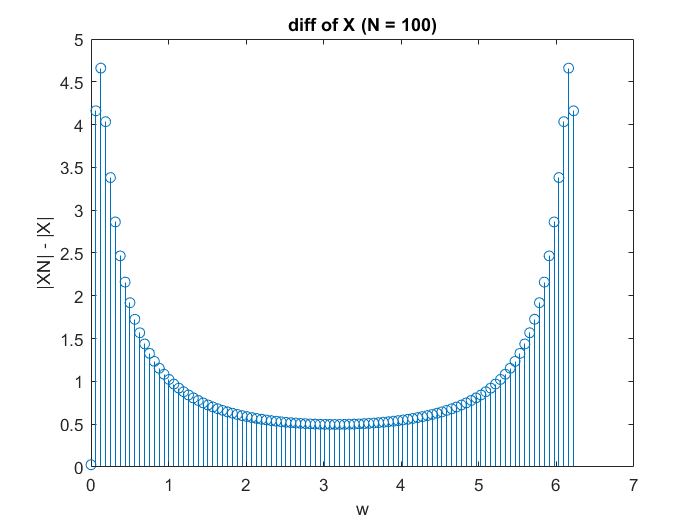


dX = XN3 - X3(1:N3);

figure
stem(w3(1:N3), abs(dX))
title('diff of X (N = 100)')
xlabel('w')
ylabel('|XN| - |X|')

幾乎沒有差別，我有特別把兩者相減 stem 出來

## 2. (a)


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =x_1 \left\lbrack n\right\rbrack +{\mathrm{jx}}_2 \left\lbrack n\right\rbrack \\
x^* \left\lbrack n\right\rbrack =x_1 \left\lbrack n\right\rbrack -{\mathrm{jx}}_2 \left\lbrack n\right\rbrack \\
x\left\lbrack n\right\rbrack \longleftrightarrow_N^{\mathrm{DFT}} X\left\lbrack k\right\rbrack \\
x^* \left\lbrack n\right\rbrack \longleftrightarrow_N^{\mathrm{DFT}} X^* \left\lbrack {\langle -k\rangle }_N \right\rbrack 
\end{array}$$



$$\begin{array}{l}
x_1 \left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack +x^* \left\lbrack n\right\rbrack \right)\\
\longleftrightarrow_N^{\mathrm{DFT}} X_1 \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack +X^* \left\lbrack {\langle -k\rangle }_N \right\rbrack \right)=X^{\mathrm{cce}} \left\lbrack k\right\rbrack 
\end{array}$$



$$\begin{array}{l}
{\mathrm{jx}}_2 \left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack -x^* \left\lbrack n\right\rbrack \right)\\
\longleftrightarrow_N^{\mathrm{DFT}} {\mathrm{jX}}_2 \left\lbrack k\right\rbrack =\frac{1}{2}\left(X\left\lbrack k\right\rbrack -X^* \left\lbrack {\langle -k\rangle }_N \right\rbrack \right)=X^{\mathrm{cco}} \left\lbrack k\right\rbrack 
\end{array}$$


## 2. (c)

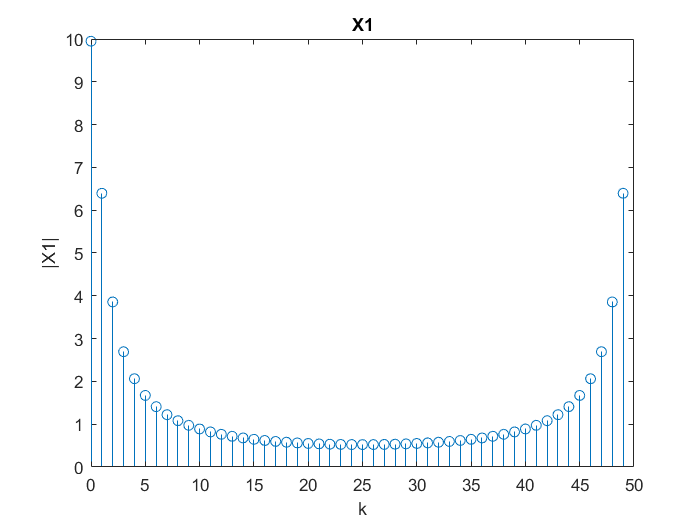

%Prob. 2(c)
n = 0:49;
x1 = 0.9.^n;
x2 = 1 - 0.8.^n;
[X1,X2] = tworealDFTs(x1,x2);
X1_dft = fft(x1);
X2_dft = fft(x2);

dX1 = X1 - X1_dft;
dX2 = X2 - X2_dft;

figure
stem(n, abs(X1))
title('X1')
xlabel('k')
ylabel('|X1|')

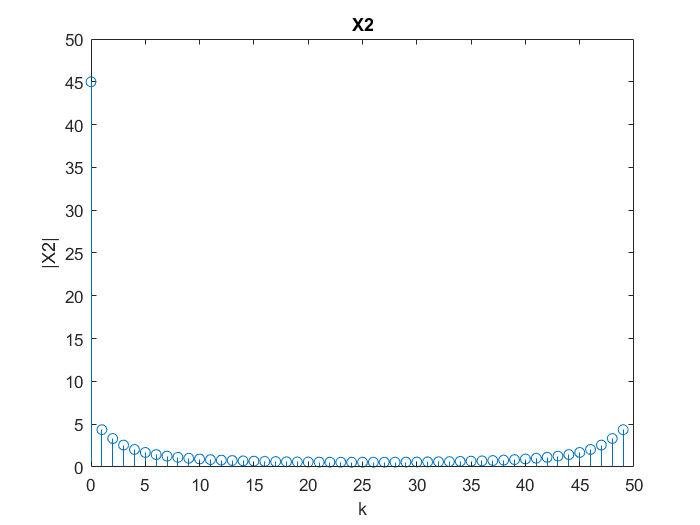


figure
stem(n, abs(X2))
title('X2')
xlabel('k')
ylabel('|X2|')

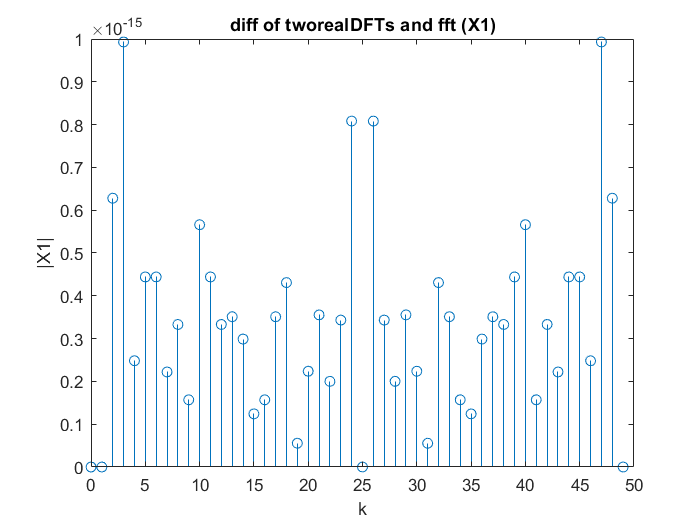


figure
stem(n, abs(dX1))
title('diff of tworealDFTs and fft (X1)')
xlabel('k')
ylabel('|X1|')

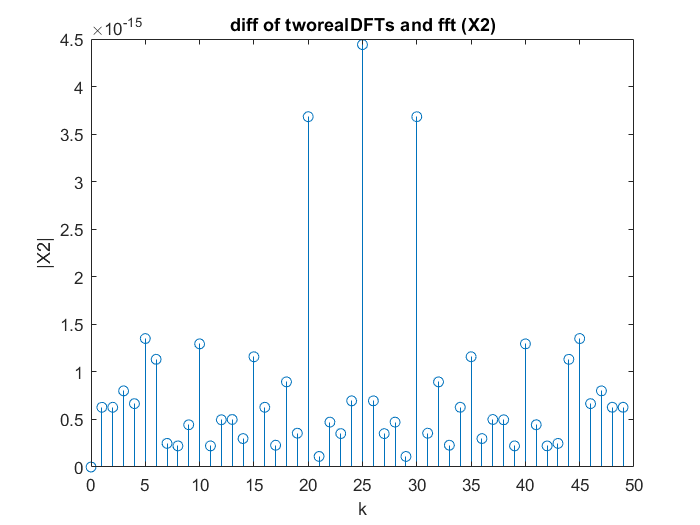


figure
stem(n, abs(dX2))
title('diff of tworealDFTs and fft (X2)')
xlabel('k')
ylabel('|X2|')

tworealDFTs 的結果與 fft 相同

## 3. (a)


$$\begin{array}{l}
x_1 \left\lbrack n\right\rbrack =\left\lbrack 1,2,3,4,5\right\rbrack \\
x_2 \left\lbrack n\right\rbrack =\left\lbrack 2,-1,1,-1,0\right\rbrack \\
y\left\lbrack n\right\rbrack =\sum_{m=0}^4 x_1 \left\lbrack n\right\rbrack x_2 \left\lbrack {\left\langle n-m\right\rangle }_N \right\rbrack \\
y\left\lbrack 0\right\rbrack =1*2+2*0+3*\left(-1\right)+4*1+5*\left(-1\right)=-2\\
y\left\lbrack 1\right\rbrack =1*\left(-1\right)+2*2+3*0+4*\left(-1\right)+5*1=4\\
y\left\lbrack 2\right\rbrack =1*1+2*\left(-1\right)+3*2+4*0+5*\left(-1\right)=0\\
y\left\lbrack 3\right\rbrack =1*\left(-1\right)+2*1+3*\left(-1\right)+4*2+5*0=6\\
y\left\lbrack 4\right\rbrack =1*0+2*\left(-1\right)+3*1+4*\left(-1\right)+5*2=7
\end{array}$$


## 3. (b)

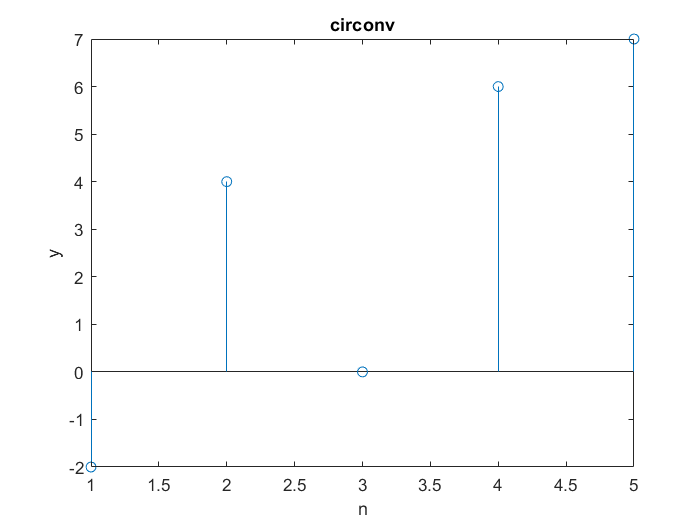

%Prob. 3(b)
x1 = [1 2 3 4 5]';
x2 = [2 -1 1 -1 0]';
y1 = circonv(x1, x2);

figure
stem(y1)
title('circonv')
xlabel('n')
ylabel('y')

it's as same as the result of 3.(a)

## 3. (c)

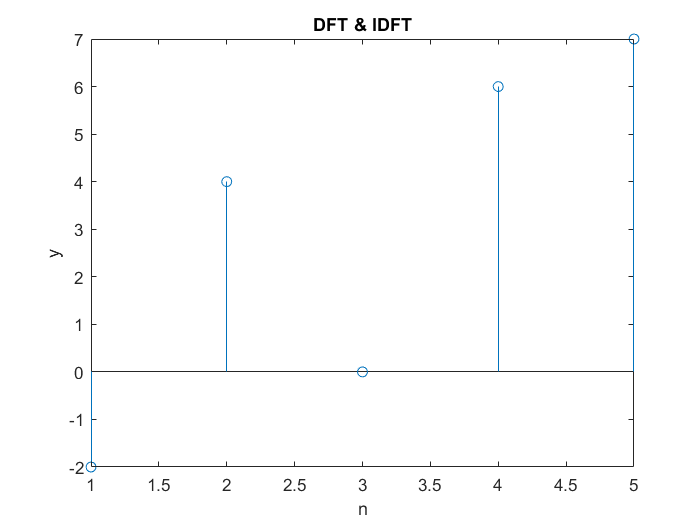

%Prob. 3(c)
X1 = fft(x1);
X2 = fft(x2);
Y2 = X1.*X2;
y2 = ifft(Y2);

figure
stem(y2)
title('DFT & IDFT')
xlabel('n')
ylabel('y')

it's as same as the result of 3.(a) 

## 4. (b)

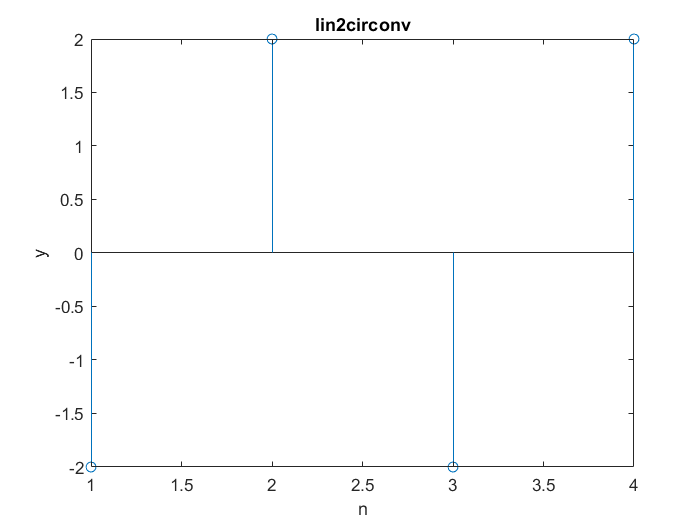

%Prob. 4(b)
x = [1 2 3 4];
h = [1 -1 1 -1];
y1 = lin2circonv(x,h);
y2 = circonv(x', h');

figure
stem(y1)
title('lin2circonv')
xlabel('n')
ylabel('y')

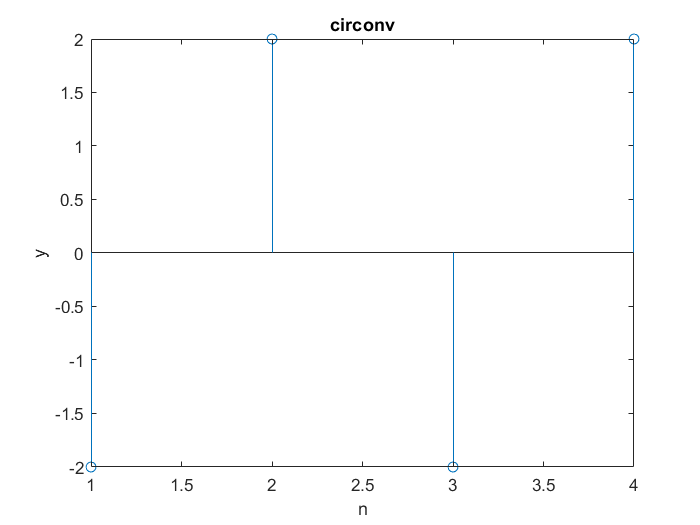


figure
stem(y2)
title('circonv')
xlabel('n')
ylabel('y')

their results are identical

## 5.

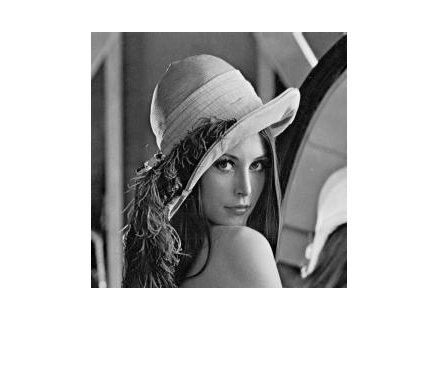

%Prob. 5
img = imread('lena.jpg');
figure
imshow(img);

## 5. (a)

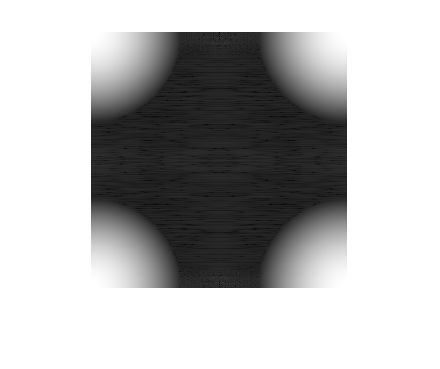

%Prob. 5(a)
m = -128:127;
n = -128:127;
sigma1 = 4;
h1 = 1/2/pi/(sigma1^2)*exp(-((m'.^2+n.^2)/2/(sigma1^2)));
h1_shift = ifftshift(h1);
H1 = fft2(h1_shift);
H1_log = log(abs(H1));
figure
imshow(H1_log, []);

## 5. (b)

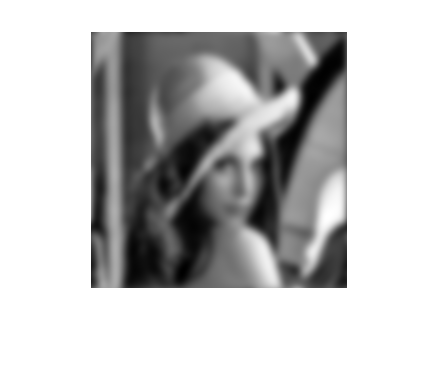

%Prob. 5(b)
img_dft = fft2(img);
Y1 = img_dft.*H1;
y1 =  ifft2(Y1);

figure
imshow(y1, [])

圖片被模糊了，像近視的人看東西一樣

## 5. (c)

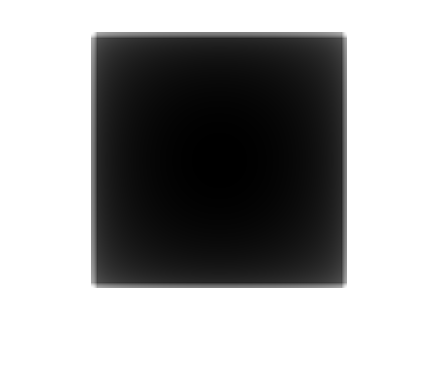

%Prob. 5(c)
sigma2 = 32;
h2 = 1/2/pi/(sigma2^2)*exp(-((m'.^2+n.^2)/2/(sigma2^2)));
h2_shift = ifftshift(h2);
H2 = fft2(h2_shift);
H2_log = log(abs(H2));

figure
imshow(H2_log, []);

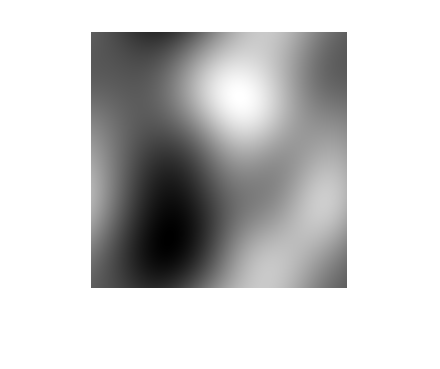


Y2 = img_dft.*H2;
y2 = ifft2(Y2);

figure
imshow(abs(y2), [])

跟 5. (b) 相比圖片更加模糊，幾乎無法辨別出本來的圖片

## 5. (d)

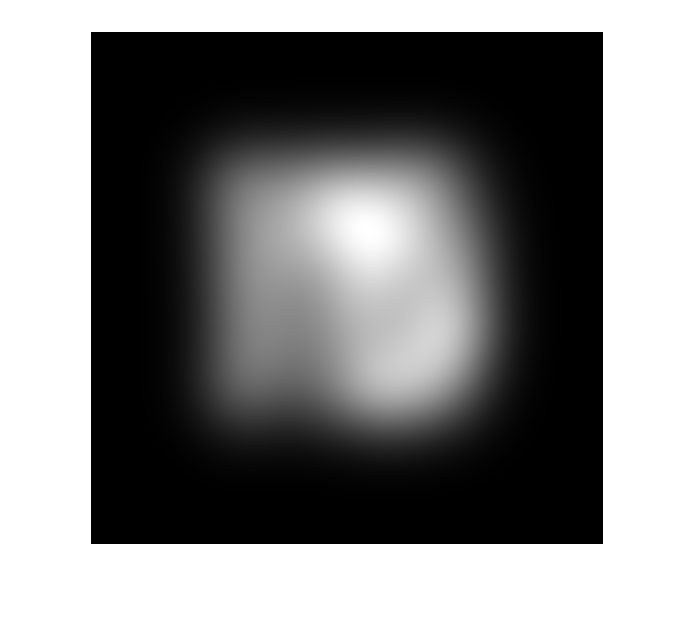

%Prob. 5(d)
img1 = padarray(img, [128 128], 0, 'both');
h3 = padarray(h2, [128 128], 0, 'both');
h3_shift = ifftshift(h3);
img1_dft = fft2(img1);
H3 = fft2(h3_shift);
Y3 = img1_dft.*H3;
y3 = ifft2(Y3);

figure
imshow(abs(y3), [])

跟 5. (c) 相比，由於有 zero padding，去除了 additional distortion，圖片只有純粹的模糊，不會因為 sigma 過大就有 distortion

## 5. (e)

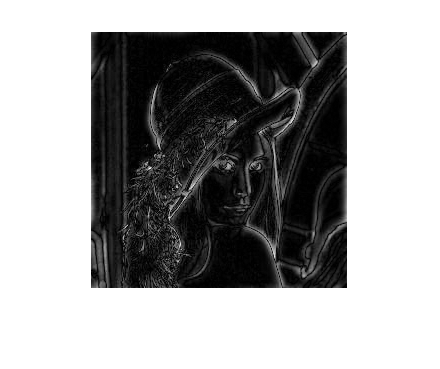

%Prob. 5(e)
H4 = 1-H1;
Y4 = img_dft.*H4;
y4 = ifft2(Y4);

figure
imshow(abs(y4), [])

可以理解為本來圖片和經過 H filter 後圖片的差異，可以發現細節都被 filter 掉了，所以此圖上充滿著細節的線條